## [Spectral Clustering](https://apmonitor.com/pds/index.php/Main/SpectralClustering)

Spectral clustering is a type of unsupervised machine learning algorithm that is used to identify clusters within a dataset. It is a variant of K-means clustering that uses the eigenvectors of a similarity matrix to perform dimensionality reduction before applying K-means. This can be useful when the data is not linearly separable or when the clusters have non-convex shapes.

The spectral clustering algorithm has the following steps:

- Calculate the similarity matrix *S* of the data points. This matrix is typically constructed using a kernel function, such as the Gaussian kernel, which measures the similarity between each pair of data points.The similarity matrix *S* is:


$$S_{\textrm{ij}} =k\left(x_i ,x_j \right)$$


where $k\left(x_i ,x_j \right)$ is the kernel function that measures the similarity between data points $x_i$ and $x_j$.

- Compute the degree matrix *D* of the similarity matrix. The degree matrix is a diagonal matrix that contains the sum of the elements in each row of the similarity matrix. The degree matrix *D* is:


$$D_{\textrm{ii}} =\sum_{j=1}^n S_{\textrm{ij}}$$


- Determine the Laplacian matrix *L* of the similarity matrix. The Laplacian matrix *L* is:


$$L=D-S$$


- Compute the eigenvectors of the Laplacian matrix. These eigenvectors, which are also known as the spectral embedding of the data, can be used to perform dimensionality reduction on the data.

- Apply K-means clustering on the spectral embedding of the data to identify clusters within the data. The eigenvectors of the Laplacian matrix can be computed by solving the following eigenvalue problem:


$$L\nu_i =\lambda_i {\;\nu }_i$$


where *v*ᵢ is the *i*-th eigenvector and $\lambda_i$ is the corresponding eigenvalue.

Once the eigenvectors have been computed, they can be used to perform dimensionality reduction on the data by projecting the data points onto the eigenvectors with the largest eigenvalues. This reduced-dimensional representation of the data can then be used as input to K-means clustering to identify clusters within the data.

Spectral clustering is known as segmentation-based object categorization. It is a technique with roots in graph theory, where identify communities of nodes in a graph are based on the edges connecting them. The method is flexible and allows clustering of non graph data as well. It uses information from the eigenvalues of special matrices built from the graph or the data set.

**Advantages:** Flexible approach for finding clusters when data doesn’t meet the requirements of other common algorithms.

**Disadvantages:** For large-sized graphs, the second eigenvalue of the (normalized) graph Laplacian matrix is often ill-conditioned, leading to slow convergence of iterative eigenvalue solvers. Spectral clustering is computationally expensive unless the graph is sparse and the similarity matrix can be efficiently constructed.

### Create Data

% Sample data
sample_size = 300; % Select a sample size

% Make an array of randomly positive and negative ones
rand = randn(sample_size,1)*0.1; 
rand = rand + (rand.*((1-abs(rand))./abs(rand)));

% Make an array to add variation to the data
std = 0.05;
variation = randn(sample_size,1)*std;

% Create two overlapping circles
x1 = linspace(1,3,sample_size-100);
x1 = [x1 linspace(1,1.1, 50) linspace(2.9,3, 50)];
y1 = (sqrt(1-(power(x1-2,2))) .* rand') + (2+variation');
x2 = linspace(2,4,sample_size-100);
x2 = [x2 linspace(2,2.1, 50) linspace(3.9,4, 50)];
y2 = (sqrt(1-(power(x2-3,2))) .* rand') + (2+variation');

### Plot Data

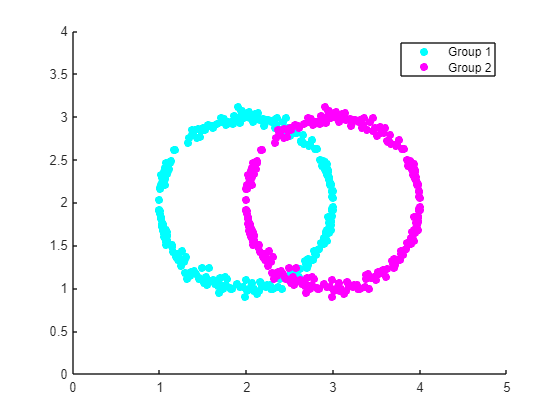

figure;
scatter(x1,y1, 'filled', 'cyan')
hold on
scatter(x2,y2, 'filled', 'magenta')
xlim([0 5]);
ylim([0 4]);
legend('Group 1', 'Group 2')
hold off

### Use Spectral Clustering

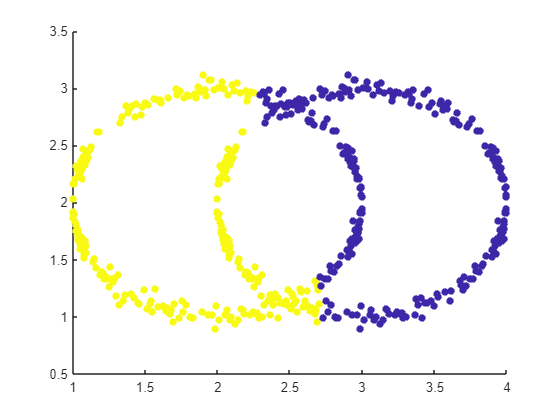

% Organize data
data = [x1' y1';x2' y2'];

% Create the similarity graph (Gaussian similarity)
sigma = 0.4;
W = exp(-pdist2(data, data).^2 / (2 * sigma^2));

% Construct the Laplacian Matrix
D = diag(sum(W, 2));  % Degree matrix
L = D - W;           % Unnormalized Laplacian

% Obtain Eigenvectors and Eigenvalues
num_clusters = 2; % Specify the number of clusters you want
[eigenvectors, eigenvalues] = eig(L);
[~, indices] = sort(diag(eigenvalues));
selected_eigenvectors = eigenvectors(:, indices(1:num_clusters));

% K-means Clustering
idx = kmeans(selected_eigenvectors, num_clusters);

% Visualization
figure;
scatter(data(:, 1), data(:, 2), 30, idx, 'filled');

The spectral clustering made a prediction that identified two groups which don't resemble the original ones, but the prediction was still reasonable. With unsupervised learning this is to be expected, the classifier isn't given labels to train with so it does its best to create its own. 

Below are a few more examples of spectral clustering predictions

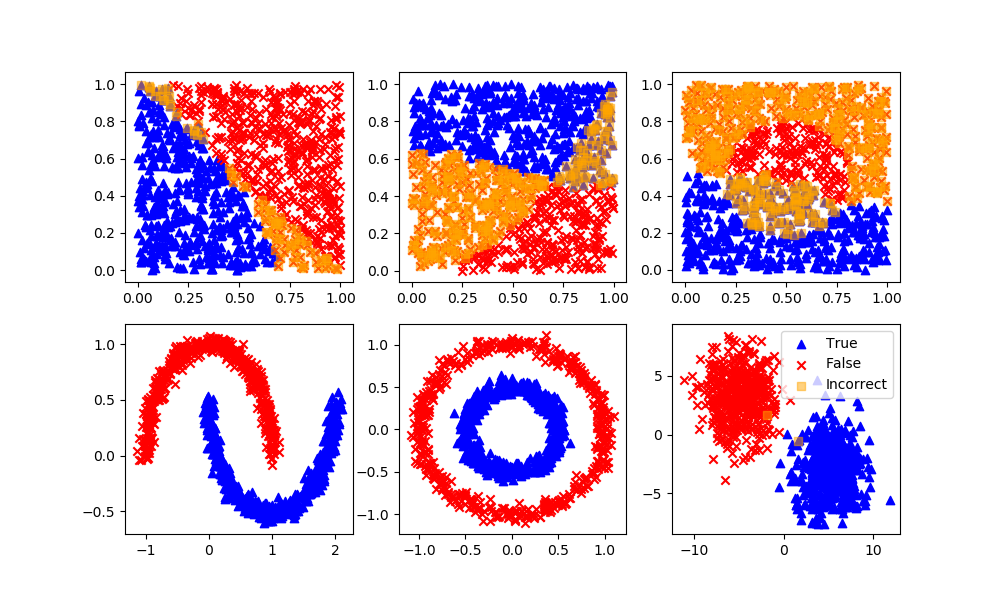

### Further Reading

[Spectral Clustering - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/stats/spectral-clustering.html)

[Spectral clustering - MATLAB spectralcluster (mathworks.com)](https://www.mathworks.com/help/stats/spectralcluster.html)

[Partition Data Using Spectral Clustering - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/stats/partition-data-using-spectral-clustering.html)